format short

N = 10;  
p = 0.55;  
q = 0.45; 

% Transition matrix
P = zeros(N+1, N+1);  
P(1,1) = 1;  
P(N+1,N+1) = 1;  

for row = 2:N
    P(row, row-1) = q; 
    P(row, row+1) = p;
end
P;
Q = P(2:N, 2:N); %transient to transient 99 x 99
R = [P(2:N, 1), P(2:N, N+1)]; %transient to absorption 99 x 2
I = eye(size(Q));
F = inv(I-Q);
H = F*R;
H_full = [P(1,1), P(1,N+1); H; P(N+1,1), P(N+1,N+1)];
r_W = H_full(:,1)

r_W =     1.0000
    0.7899
    0.6181
    0.4775
    0.3624
    0.2683
    0.1913
    0.1283
    0.0767
    0.0345


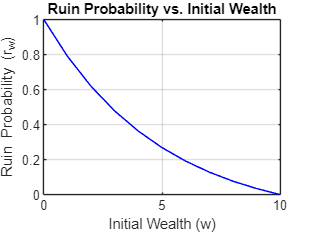

figure;
plot(0:N, r_W, 'b', 'LineWidth', 1);
xlabel('Initial Wealth (w)');
ylabel('Ruin Probability (r_w)');
title(['Ruin Probability vs. Initial Wealth']);
grid on;